# SAR第三次作业——星载SAR数据成像实验报告

姓名：周志龙                学号：24216226

- 实验要求

- 实验原理

- 仿真源码与结果

## 实验要求

对Radarsat-1星载SAR的原始回波数据进行成像，使用RDA以及CS成像算法实现

其中RDA算法采用课上提到的最好的第二种方法，即**实现二次距离压缩**的RDA算法

同时尝试使用CS(Chirp Scaling)算法进行回波数据的成像

## 实验原理

实现二次距离压缩的RDA算法框图：

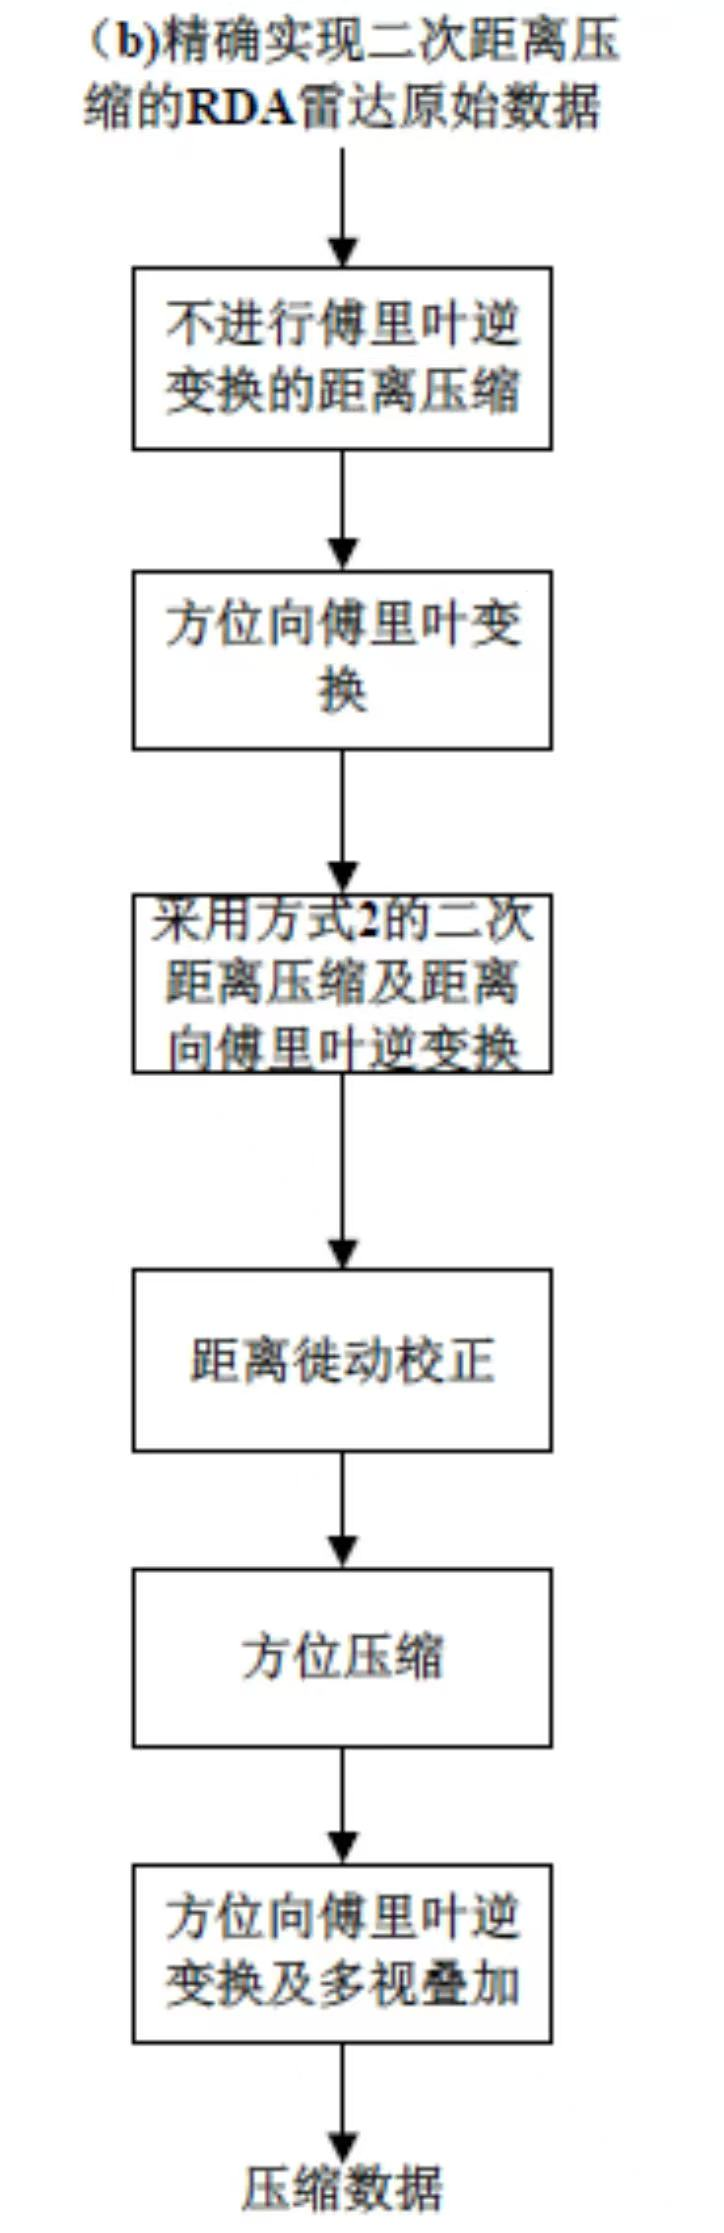

## 仿真源码与结果

首先要进行原始数据的提取，这里提前用specify_parameters生成了CDdata1.mat 与 CDdata2.mat

其中本人修改了一下参数（直接输入了绝对路径进行数据提取）

程序可以直接使用CDdata数据即可运行，无需再提取数据

得到的原始数据需要转换为double类型方便后续的处理

这里给出了数据提取的代码并显示原始数据的图像

clear;
clc;
close all;

% 载入参数
param = load('CD_run_params');
% 原始数据提取
raw_dat = load('CD_Data_Processing\CDdata1.mat');
% raw_dat为struct格式，其中raw_data.data代表的为原始回波数据
% 用double转换为双精度浮点类型数据，便于后续进行计算
s_echo = double(raw_dat.data);

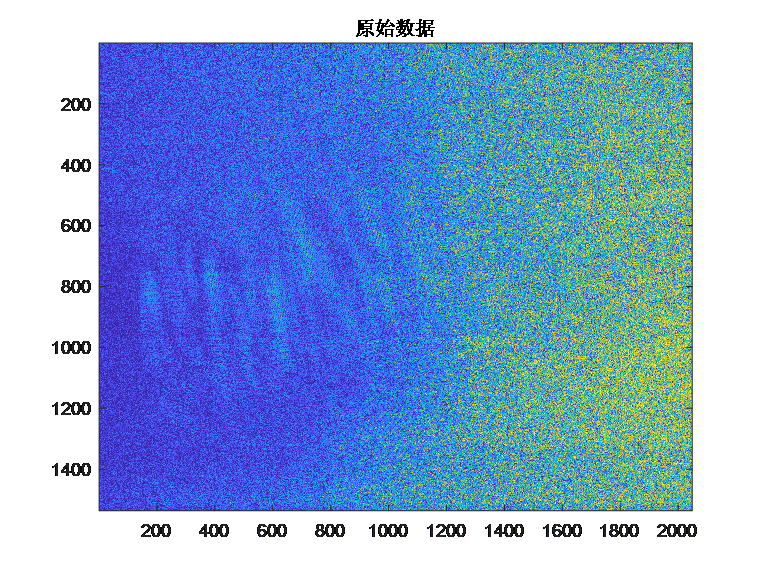

接下来需要读取CD_run_params.mat中给出的一些参数，并参考Wong-合成孔径雷达成像: 算法与实现

一书中给出的一些参数，定义系统中的参数。同时按照距离与方位向的线数来定义距离向和方位向时域和频域。

f0 = param.f0;                  % 载波频率f0
c = param.c;                    % 光速
Kr = -param.Kr;                 % 调频率Kr
BW_range = 30.111e+06;          % 脉冲宽度
Vr = 7062;                      % 有效雷达速率（书中给出）
Ka = 1733;                      % 方位调频率（书中给出）
fnc = -6900;                    % 多普勒中心频率（书中给出）
Fa = param.PRF;                 % 方位向采样率
R0 = param.R0;                  % R0
lamda = c/f0;                   % 波长
T_start = 6.5959e-03;           % 数据窗开始时间
Tr = param.Tr;                  % 距离向脉宽Tr
Fr = param.Fr;                  % 距离向采样频率Fr
Nr = round(Tr*Fr);              % 线性调频信号采样点数
Nrg = param.Nrg_cells;          % 距离线采样点数
Naz = param.Nrg_lines_blk;     	% 每一个数据块的距离线数
first_rg_cell = param.first_rg_cell;
first_rg_line = param.first_rg_line;
NFFT_r = Nrg;                   % 距离向FFT长度
NFFT_a = Naz;                   % 方位向FFT长度
% 距离向
tr = T_start + ( -Nrg/2 : (Nrg/2-1) )/Fr;                       % 距离时间轴
fr = ( -NFFT_r/2 : NFFT_r/2-1 )*( Fr/NFFT_r );                  % 距离频率轴
% 方位向
ta = ( -Naz/2: Naz/2-1 )/Fa;                                    % 方位时间轴
fa = fnc + fftshift( -NFFT_a/2 : NFFT_a/2-1 )*( Fa/NFFT_a );	% 方位频率轴

接下来按照实验原理中给出的二次距离压缩的RDA算法步骤实现RDA算法，第一步，进行第一次的距离向压缩

第一次距离压缩后得到的结果图像如下

%% RDA算法实现 1.距离压缩
S_range = fft(s_echo,NFFT_r,2);     % 进行距离向傅里叶变换，零频在两端

t_ref = ( -Nr/2 : (Nr/2-1) )/Fr;    % LFM信号的时域轴
t_ref_mtx = ones(Naz,1)*t_ref;      % 时域轴的矩阵形式
s_ref = exp((1j*pi*Kr).*((t_ref_mtx).^2)); % LFM的时域表达式s_ref
s_ref = [s_ref,zeros(Naz,Nrg-Nr)];         % 时域补零

S_ref = fft(s_ref,NFFT_r,2);            % 对LFM信号进行距离傅里叶变换得到频域表达式
H_range = conj(S_ref);                  % 取共轭得到距离向匹配滤波器的频域表达式
S_range_c = S_range.*H_range;           % 频域乘以匹配滤波器，得到距离压缩的频域
s_rc = ifft(S_range_c,[],2);            % ifft，完成距离向压缩


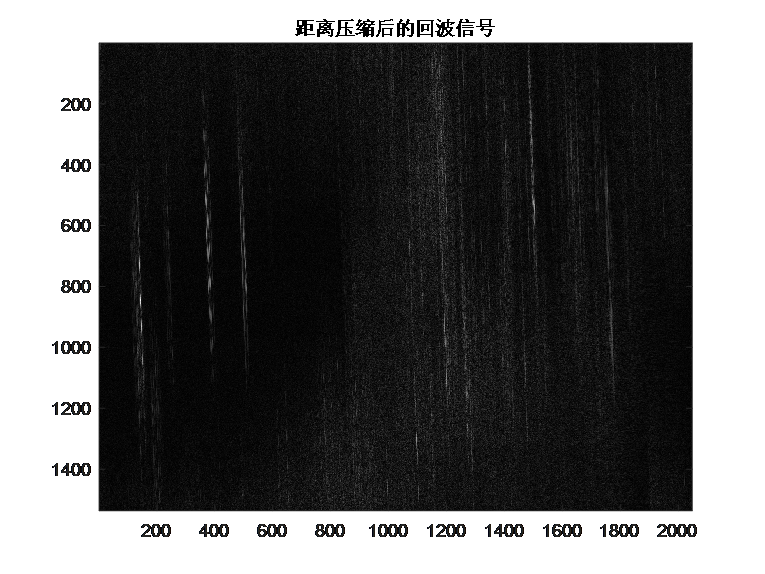

第二步，进行方位向傅里叶变换，并参考方式2进行二次距离压缩与距离向傅里叶逆变换

% 由于多普勒不在零频，所以需要在时域乘线性相位项，进行频域搬移
s_rc = s_rc.*exp(-1j*2*pi*fnc.*(ta.'*ones(1,Nrg)));
% 然后进行距离向傅里叶变换
S_2df = fft(s_rc,NFFT_a,1);         	% 方位向傅里叶变换，到距离多普勒域
S_2df = fft(S_2df,Nrg,2);               % 距离向傅里叶变换，到二维频域

% 定义方位频率轴
fa = fnc + fftshift(-NFFT_a/2:NFFT_a/2-1)/NFFT_a*Fa;

D_fn_Vr = sqrt(1-lamda^2.*(fa.').^2./(4*Vr^2));         % 大斜视角下的徙动因子

K_src = 2*Vr^2*f0^3.*D_fn_Vr.^3./(c*R0*(fa.').^2);      % 列向量定义
K_src_1 = 1./K_src;             % 为了后面能使用矩阵乘法，这里先求倒数
H_src = exp(-1j*pi.*K_src_1*(fr.^2)); % 二次距离压缩滤波器
% 这是矩阵，大小Naz*Nrg
H_src = fftshift(H_src,2);      % （左右半边互换）距离向，零频在两端

S_2df_src = S_2df.*H_src;       % 进行二次距离压缩

S_rd = ifft(S_2df_src,[],2);   	% 完成二次距离压缩（SRC），回到距离多普勒域。


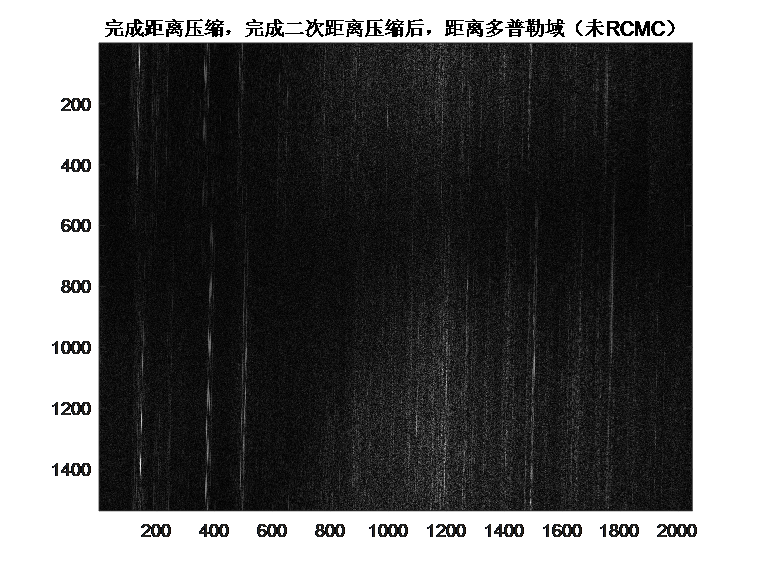

第三步，进行RCMC距离徒动校正

% 定义用于RCMC和方位压缩的距离时间轴。
tr_RCMC = T_start + ( -Nrg/2 : (Nrg/2-1) )/Fr;  
R0_RCMC = (c/2).*tr_RCMC;   % 随距离线变化的R0
delta_Rrd_fn = ((1-D_fn_Vr)./D_fn_Vr)*R0_RCMC;      % 大斜视角下的RCM

num_range = c/(2*Fr);   % 一个距离采样单元，对应的长度
delta_Rrd_fn_num = delta_Rrd_fn./num_range; % 每一个方位向频率，其RCM对应的距离采样单元数

R = 8;  % sinc插值核长度
S_rd_rcmc = zeros(NFFT_a,Nrg); % 用来存放RCMC后的值
for p = 1 : NFFT_a
    for q = 1 : Nrg   % 此时距离向的长度是 (Nrg-Nr+1)=Nrg        
        delta_Rrd_fn_p = delta_Rrd_fn_num(p,q);
        Rrd_fn_p = q + delta_Rrd_fn_p;
        
        Rrd_fn_p = rem(Rrd_fn_p,Nrg);  % 由于RCM的长度会超过Nrg，所以这样处理一下。
        
        Rrd_fn_p_zheng = ceil(Rrd_fn_p);        % ceil，向上取整。
        ii = ( Rrd_fn_p-(Rrd_fn_p_zheng-R/2):-1:Rrd_fn_p-(Rrd_fn_p_zheng+R/2-1)  );        
        rcmc_sinc = sinc(ii);
        rcmc_sinc = rcmc_sinc/sum(rcmc_sinc);   % 插值核的归一化
        % ii 是sinc插值过程的变量;
        % g(x)=sum(h(ii)*g_d(x-ii)) = sum(h(ii)*g_d(ll));
               
        % 由于S_rd只有整数点取值，且范围有限。因此插值中要考虑它的取值溢出边界问题。
        % 这里我采取循环移位的思想，用来解决取值溢出问题。
        if (Rrd_fn_p_zheng-R/2) > Nrg    % 全右溢
            ll = (Rrd_fn_p_zheng-R/2-Nrg:1:Rrd_fn_p_zheng+R/2-1-Nrg);
        else
            if (Rrd_fn_p_zheng+R/2-1) > Nrg    % 部分右溢
                ll_1 = (Rrd_fn_p_zheng-R/2:1:Nrg);
                ll_2 = (1:1:Rrd_fn_p_zheng+R/2-1-Nrg);
                ll = [ll_1,ll_2];
            else
                if (Rrd_fn_p_zheng+R/2-1) < 1    % 全左溢（不可能发生，但还是要考虑）
                    ll = (Rrd_fn_p_zheng-R/2+Nrg:1:Rrd_fn_p_zheng+R/2-1+Nrg);
                else
                    if (Rrd_fn_p_zheng-R/2) < 1       % 部分左溢
                        ll_1 = (Rrd_fn_p_zheng-R/2+Nrg:1:Nrg);
                        ll_2 = (1:1:Rrd_fn_p_zheng+R/2-1);
                        ll = [ll_1,ll_2];
                    else
                        ll = (Rrd_fn_p_zheng-R/2:1:Rrd_fn_p_zheng+R/2-1);
                    end                    
                end
            end
        end   
        rcmc_S_rd = S_rd(p,ll);
        S_rd_rcmc(p,q) = sum( rcmc_sinc.*rcmc_S_rd );
    end
end
% S_rd_rcmc 就是RCMC后的距离多普勒域频谱。


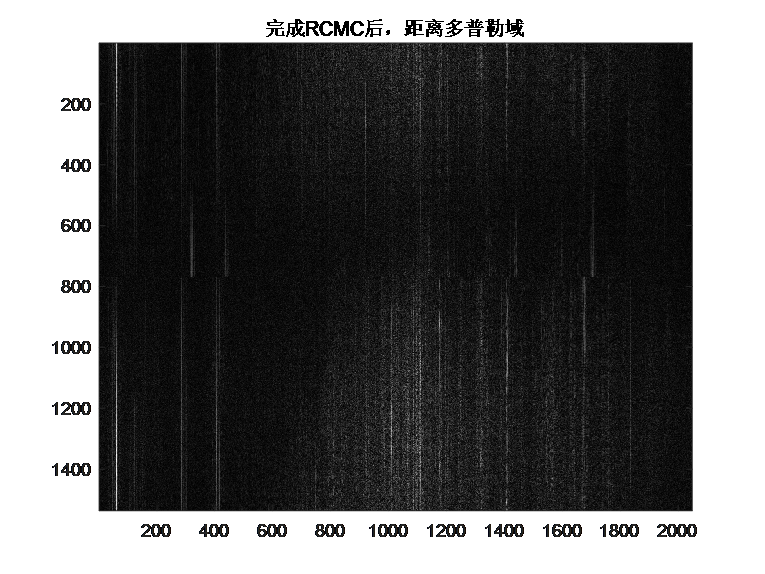

最后，进行方位向压缩得到最终的RDA成像结果

fa_azimuth_MF = fa;         % 方位频率轴，采用和RCMC中所用的频率轴相同。
Haz = exp(1j*4*pi.*(D_fn_Vr*R0_RCMC).*f0./c);   % 改进的方位向匹配滤波器

S_rd_c = S_rd_rcmc.*Haz;            % 乘以匹配滤波器
s_ac = ifft(S_rd_c,[],1);       	% ifft，完成方位压缩

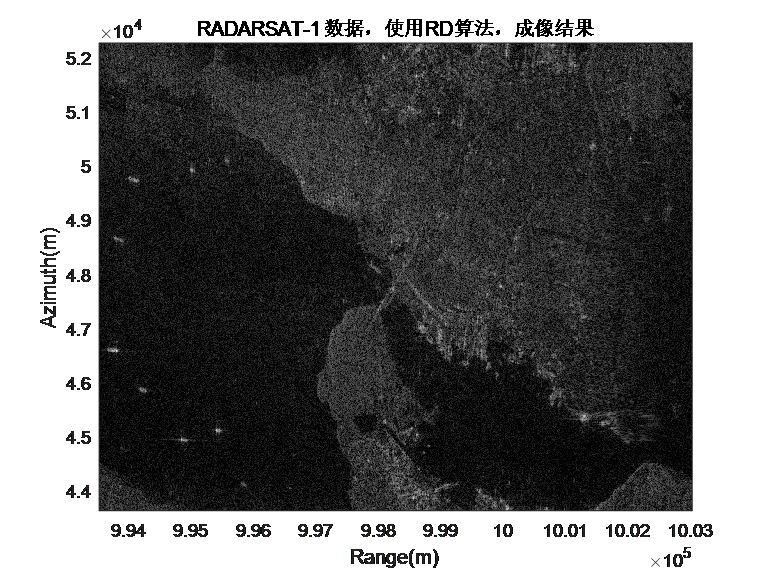

## 参考文献

【0】中山大学电子与通信工程学院-合成孔径雷达成像技术

【1】Wong L G C F H . 合成孔径雷达成像: 算法与实现[M]. 电子工业出版社, 2012.

【2】基于RD小斜视算法的Radarsat-1回波数据处理与成像 https://www.bilibili.com/video/BV1ti4y1v7sQ